**Introduction: What is a mask?**

A mask in health is a protective covering worn over the nose and mouth to help prevent the spread of respiratory infections, such as COVID-19. Masks can filter out harmful particles and reduce the transmission of germs between individuals. However, the question to ask is “how effective does a mask have to be to substantially reduce the spread of a disease?”

**Baseline Dataset (no masks):**

First we define our parameters for the baseline data set:

S_1 = 99;% Susceptible people
I_1 = 1; % Infected people
R_1 = 0; % Recovered people
Q_1 = 0; %Quarantined people

i = 0.9; % Infectivity rate is 90% according to the CDC
r = 0.0714; % The average person takes two weeks to recover

m = .05; % Mask effectiveness (1 is worst, 0 is best) (.05 is for a KN95 mask, which has become standard after covid)

ob = 1; %obedience, (1 means everyone is compliant). Also directly proportional to quarantined population

t_end = 40; % Time simulation end, in weeks

countermeasure_reduction_value = 1-(m*ob);

These parameters define the infectivity rate, the recovery rate, and the initial starting infected and healthy population. The initial recovered rate is always 0. 

**Next we run it through our equations: **

% Normal Model
% S(t+1) = S(t) - (I(t) * S(t) * i)
% I(t+1) = I(t) + (I(t) * S(t) * i) - (I(t) * r)
% R(t+1) = R(t) + (I(t) * r)

% Mask Model
% S(t+1) = S(t) - (I(t) * S(t) * i * m)
% I(t+1) = I(t) + (I(t) * S(t) * i * m) - (I(t) * r)
%add quartentined value that takes obedience as a percetange from
%infected. Ex. A .8 obidenece would take 80% of the infected and put them
%in quarentine instead of infected state. 
% R(t+1) = R(t) + (I(t) * r)

These equations allow us to model the spread of the disease and how masks will impact it, allowing us to do a comparison on how masks affect the spread of disease. 

**Now we get our baseline data plot:**

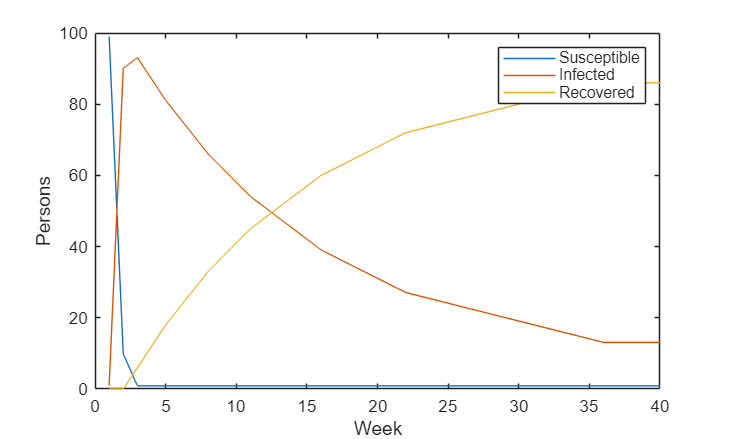

[S, I, R, W] = simulate_sir(S_1, I_1, R_1, m, i, r, t_end);

% Plot - baseline
figure()
plot(W, S, 'DisplayName', 'Susceptible'); hold on
plot(W, I, 'DisplayName', 'Infected')
plot(W, R, 'DisplayName', 'Recovered')

xlabel("Week")
ylabel("Persons")
legend()

This data plot shows a large spike in infectivity right at the start, which aligns with the statement from the CDC about measles being one of the most infective diseases known to man, with a roughly 90% infectivity rate. The recovered population curves, as to be expected with it taking on average 14 days for an individual to fully recover, as stated by the CDC.

**Finding the mask effectiveness that cuts the peak infected number to 50% of the original value: **

To find the mask effectiveness value that would cut the peak infected population by 50%, we performed a parameter sweep by graphing a range of effectiveness values against their respective peak infected population until we find one that is 50% of the peak infected population when mask effectiveness is 1 (no masks being worn).

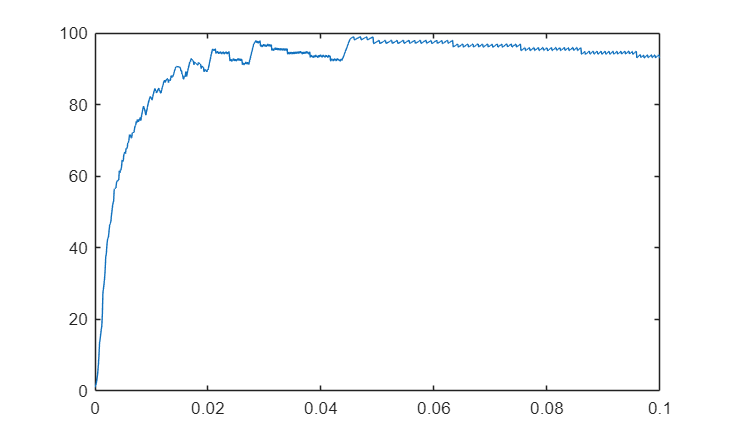

maxI = max(I);
idealI = maxI/2;
IxMax = zeros(1, 1000);
MiList = .1:-0.0001:0;
answer = 0;
count = 1;

for mi = MiList
    [Sx, Ix, Rx, Wx] = simulate_sir(S_1, I_1, R_1, mi, i, r, t_end);
    IxMax(count) = max(Ix);
    count = count + 1;
end
figure()
plot(MiList, IxMax, 'DisplayName', 'wahhhhh')

for mi = MiList
    [Sx, Ix, Rx, Wx] = simulate_sir(S_1, I_1, R_1, mi, i, r, t_end);
    if idealI > max(Ix)
        answer = mi;
        break
    end
end
answer

answer = 0.0026

Our results show that a minumum effectiveness of 99.74% will reduce the peak infected population by 50%. Masks such as the Elastomeric respirator (with P100 filters) or better would be ideal during a measles outbreak. While this does not account for recovered people getting reinfected, this model can help us recommend a mask for a given population to wear.